# Dimensionality reduction

The training examples in "split.mat" contains 30 features, and you can assume the data has been properly prepared:

clear all;
load('split.mat', 'train_examples');

Use Principal Components Analysis to investigate reducing the dimensionality of the resulting feature space.

Marks are available for:

- Applying appropriate pre-processing steps to the data [4 marks]

- Recovering the principal components, and the transformed data [4 marks]

- Taking sensible steps to decide on how many principle components to retain and recording your findings in a comment [6 marks]

- Creating the new lower-dimensional dataset [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

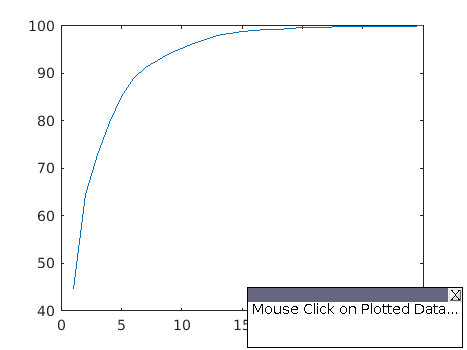

% add as many lines of code as you need below:
%Pre-processing z-score standartization
  %getting the average value of the training examples
			m.mean = mean(train_examples{:,:});
			%getting the measure of the features overall spread
            %(how many individual features tend to differ from their mean)
            m.std = std(train_examples{:,:});
            for i=1:size(train_examples,1)
                % substracting the average (mean) value
				train_examples{i,:} = train_examples{i,:} - m.mean;
                %devision by the standart deviation value
                train_examples{i,:} = train_examples{i,:} ./ m.std;
            end
%Recovering the principal components
[principal_components, data_transformed, ~, ~, explained] = pca(train_examples{:,:});
%how many principle components to retain
plot(cumsum(explained));
dcm = datacursormode;
dcm.Enable = 'on';

dcm.DisplayStyle = 'window';
%keeping 15PCs - creating the new lower-dimensional dataset
data_reduced = data_transformed(:, 1:1:15);
